
clc;
close all;
clear all;
xn=input('Enter the input sequence=');
ln=length(xn);
xk=zeros(1,ln);
ixk=zeros(1,ln);
%obtain DFT
for k=0:ln-1
for n=0:ln-1
xk(k+1)=xk(k+1)+(xn(n+1)*exp((-i)*2*pi*k*n/ln));
end
end
t=0:ln-1;
subplot(221);
stem(t,xn);
ylabel('amplitude');
xlabel('time index');
title('input sequence');
%magnitude plot
magnitude=abs(xk);
t=0:ln-1;
subplot(222);
stem(t,magnitude);
ylabel('amplitude');
xlabel('k');
title('magnitude responce');
%phase responce
phase=angle(xk);
t=0:ln-1;
subplot(223);
stem(t,phase);
title('phase responce');
% inverse DFT
ixk=ixk./ln;
t=0:ln-1;
subplot(224);
stem(t,xn);
ylabel('amplitude');
xlabel('time index');
1

ans = 1

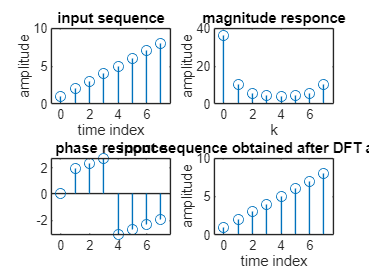

title('input sequence obtained after DFT and IDFT');

%12564
